clc;
clear all;
close all;
%..............................................................
% Initiation
%..............................................................
no_of_data_bits = 64%Number of bits per channel extended to 128

no_of_data_bits = 64

M =4%Number of subcarrier channel

M = 4

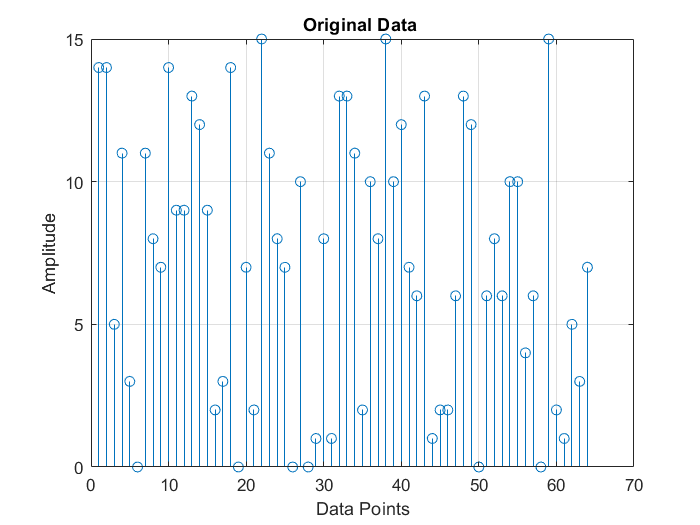

n=256;%Total number oGGgf bits to be transmitted at the transmitter
block_size = 16; %Size of each OFDM block to add cyclic prefix
cp_len = floor(0.1 * block_size); %Length of the cyclic prefix
%............................................................
% Transmitter
%.........................................................
%.........................................................
% Source generation and modulation
%........................................................
% Generate random data source to be transmitted of length 64
data = randsrc(1, no_of_data_bits, 0:15);
figure(1),stem(data); grid on; xlabel('Data Points'); ylabel('Amplitude')
title('Original Data ')

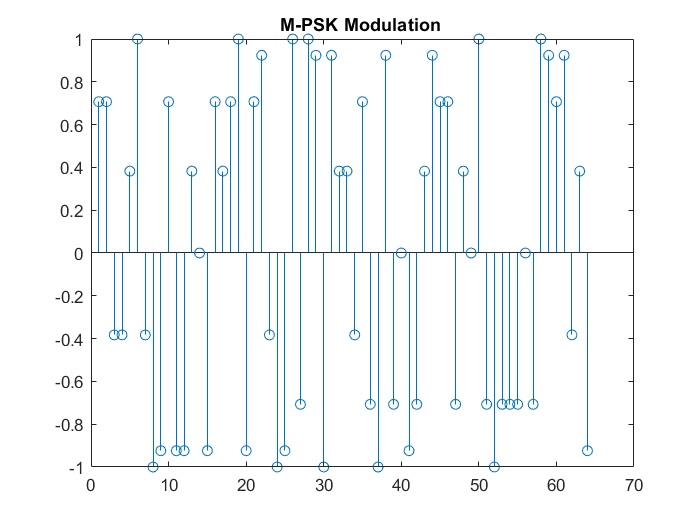

% Perform QPSK modulation on the input source data
m_psk_modulated_data = pskmod(data, block_size);
figure(2),stem(m_psk_modulated_data);title('M-PSK Modulation ')

%............................................................
%.............................................................
% Converting the series data stream into four parallel data stream to form
% four sub carriers
S2P = reshape(m_psk_modulated_data, no_of_data_bits/M,M)

S2P =    0.7071 - 0.7071i   0.3827 + 0.9239i   0.3827 - 0.9239i  -0.0000 - 1.0000i
   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.3827 - 0.9239i   1.0000 + 0.0000i
  -0.3827 + 0.9239i   1.0000 + 0.0000i   0.7071 + 0.7071i  -0.7071 + 0.7071i
  -0.3827 - 0.9239i  -0.9239 + 0.3827i  -0.7071 - 0.7071i  -1.0000 + 0.0000i
   0.3827 + 0.9239i   0.7071 + 0.7071i  -1.0000 + 0.0000i  -0.7071 + 0.7071i
   1.0000 + 0.0000i   0.9239 - 0.3827i   0.9239 - 0.3827i  -0.7071 - 0.7071i
  -0.3827 - 0.9239i  -0.3827 - 0.9239i  -0.7071 - 0.7071i  -0.7071 - 0.7071i
  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i   0.0000 + 1.0000i
  -0.9239 + 0.3827i  -0.9239 + 0.3827i  -0.9239 + 0.3827i  -0.7071 + 0.7071i
   0.7071 - 0.7071i   1.0000 + 0.0000i  -0.7071 + 0.7071i   1.0000 + 0.0000i


Sub_carrier1 = S2P(:,1)

Sub_carrier1 =    0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.3827 + 0.9239i
  -0.3827 - 0.9239i
   0.3827 + 0.9239i
   1.0000 + 0.0000i
  -0.3827 - 0.9239i
  -1.0000 + 0.0000i
  -0.9239 + 0.3827i
   0.7071 - 0.7071i


Sub_carrier2 = S2P(:,2)

Sub_carrier2 =    0.3827 + 0.9239i
   0.7071 - 0.7071i
   1.0000 + 0.0000i
  -0.9239 + 0.3827i
   0.7071 + 0.7071i
   0.9239 - 0.3827i
  -0.3827 - 0.9239i
  -1.0000 + 0.0000i
  -0.9239 + 0.3827i
   1.0000 + 0.0000i


Sub_carrier3 = S2P(:,3)

Sub_carrier3 =    0.3827 - 0.9239i
  -0.3827 - 0.9239i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -1.0000 + 0.0000i
   0.9239 - 0.3827i
  -0.7071 - 0.7071i
  -0.0000 - 1.0000i
  -0.9239 + 0.3827i
  -0.7071 + 0.7071i


Sub_carrier4 = S2P(:,4)

Sub_carrier4 =   -0.0000 - 1.0000i
   1.0000 + 0.0000i
  -0.7071 + 0.7071i
  -1.0000 + 0.0000i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.0000 + 1.0000i
  -0.7071 + 0.7071i
   1.0000 + 0.0000i



figure(3), subplot(4,1,1),stem(Sub_carrier1),title('Subcarrier1'),grid on;

subplot(4,1,2),stem(Sub_carrier2),title('Subcarrier2'),grid on;

subplot(4,1,3),stem(Sub_carrier3),title('Subcarrier3'),grid on;

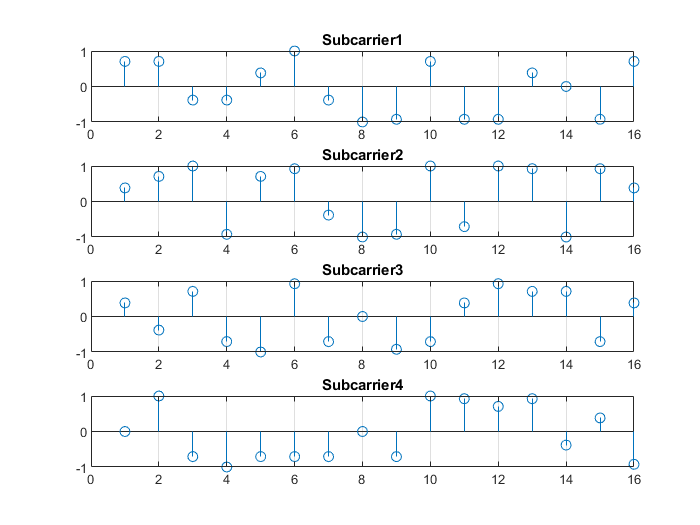

subplot(4,1,4),stem(Sub_carrier4),title('Subcarrier4'),grid on;


%..................................................................
%..................................................................
% IFFT OF FOUR SUB_CARRIERS
%.................................................................
%..............................................................
number_of_subcarriers=4;
cp_start=block_size-cp_len;
ifft_Subcarrier1 = ifft(Sub_carrier1)

ifft_Subcarrier1 =   -0.0781 - 0.2565i
   0.0306 + 0.1135i
  -0.0065 + 0.0239i
   0.3027 - 0.1315i
   0.3110 + 0.2784i
   0.0048 - 0.4389i
   0.0983 - 0.1175i
   0.1541 + 0.0099i
  -0.1800 + 0.1202i
  -0.1254 + 0.0093i


ifft_Subcarrier2 = ifft(Sub_carrier2)

ifft_Subcarrier2 =    0.1884 - 0.0302i
   0.1868 + 0.0110i
  -0.1206 + 0.0354i
   0.2310 - 0.2039i
   0.0503 + 0.3636i
  -0.3591 - 0.1000i
  -0.2377 + 0.2106i
   0.2325 + 0.1545i
   0.0521 + 0.1737i
   0.2553 + 0.2429i


ifft_Subcarrier3 = ifft(Sub_carrier3)

ifft_Subcarrier3 =   -0.0011 - 0.1370i
   0.2939 - 0.2123i
  -0.1616 - 0.1437i
   0.1836 - 0.1019i
  -0.1791 + 0.0203i
   0.0439 - 0.2696i
   0.0371 - 0.2675i
   0.2314 + 0.1520i
  -0.1437 + 0.1306i
  -0.0327 + 0.1334i


ifft_Subcarrier4 = ifft(Sub_carrier4)

ifft_Subcarrier4 =   -0.0565 + 0.2278i
   0.0577 - 0.3174i
   0.0836 + 0.1321i
   0.0785 - 0.2114i
   0.0931 + 0.1489i
  -0.1254 - 0.0386i
  -0.1202 + 0.0239i
   0.2233 + 0.1541i
  -0.0182 - 0.0605i
  -0.0099 - 0.0999i


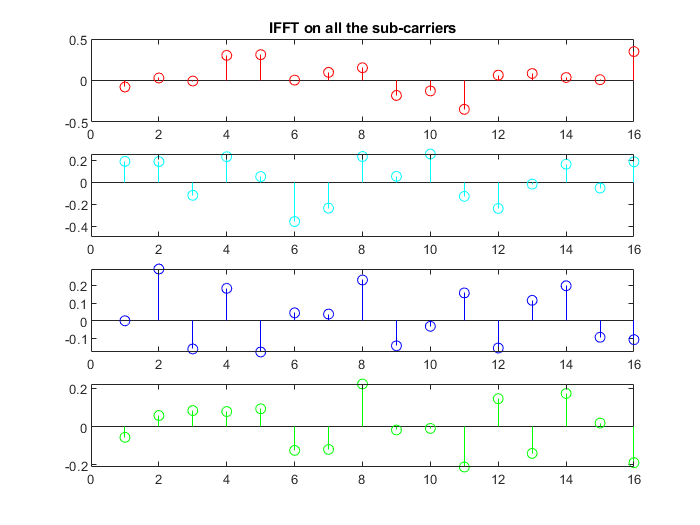

figure(4), subplot(4,1,1),stem(real(ifft_Subcarrier1),'r'),
title('IFFT on all the sub-carriers')
subplot(4,1,2),stem(real(ifft_Subcarrier2),'c')
subplot(4,1,3),stem(real(ifft_Subcarrier3),'b')
subplot(4,1,4),stem(real(ifft_Subcarrier4),'g')

%...........................................................
%...........................................................
% ADD-CYCLIC PREFIX %..........................................................
%............................................................
for i=1:number_of_subcarriers
ifft_Subcarrier(:,i) = ifft((S2P(:,i)),16)% 16 is the ifft point
for j=1:cp_len
cyclic_prefix(j,i) = ifft_Subcarrier(j+cp_start,i)
end
Append_prefix(:,i) = vertcat( cyclic_prefix(:,i), ifft_Subcarrier(:,i))
% Appends prefix to each subcarriers
end

ifft_Subcarrier =   -0.0781 - 0.2565i
   0.0306 + 0.1135i
  -0.0065 + 0.0239i
   0.3027 - 0.1315i
   0.3110 + 0.2784i
   0.0048 - 0.4389i
   0.0983 - 0.1175i
   0.1541 + 0.0099i
  -0.1800 + 0.1202i
  -0.1254 + 0.0093i


cyclic_prefix = 0.3484 - 0.0785i

Append_prefix =    0.3484 - 0.0785i
  -0.0781 - 0.2565i
   0.0306 + 0.1135i
  -0.0065 + 0.0239i
   0.3027 - 0.1315i
   0.3110 + 0.2784i
   0.0048 - 0.4389i
   0.0983 - 0.1175i
   0.1541 + 0.0099i
  -0.1800 + 0.1202i


ifft_Subcarrier =   -0.0781 - 0.2565i   0.1884 - 0.0302i
   0.0306 + 0.1135i   0.1868 + 0.0110i
  -0.0065 + 0.0239i  -0.1206 + 0.0354i
   0.3027 - 0.1315i   0.2310 - 0.2039i
   0.3110 + 0.2784i   0.0503 + 0.3636i
   0.0048 - 0.4389i  -0.3591 - 0.1000i
   0.0983 - 0.1175i  -0.2377 + 0.2106i
   0.1541 + 0.0099i   0.2325 + 0.1545i
  -0.1800 + 0.1202i   0.0521 + 0.1737i
  -0.1254 + 0.0093i   0.2553 + 0.2429i


cyclic_prefix =    0.3484 - 0.0785i   0.1847 + 0.0829i


Append_prefix =    0.3484 - 0.0785i   0.1847 + 0.0829i
  -0.0781 - 0.2565i   0.1884 - 0.0302i
   0.0306 + 0.1135i   0.1868 + 0.0110i
  -0.0065 + 0.0239i  -0.1206 + 0.0354i
   0.3027 - 0.1315i   0.2310 - 0.2039i
   0.3110 + 0.2784i   0.0503 + 0.3636i
   0.0048 - 0.4389i  -0.3591 - 0.1000i
   0.0983 - 0.1175i  -0.2377 + 0.2106i
   0.1541 + 0.0099i   0.2325 + 0.1545i
  -0.1800 + 0.1202i   0.0521 + 0.1737i


ifft_Subcarrier =   -0.0781 - 0.2565i   0.1884 - 0.0302i  -0.0011 - 0.1370i
   0.0306 + 0.1135i   0.1868 + 0.0110i   0.2939 - 0.2123i
  -0.0065 + 0.0239i  -0.1206 + 0.0354i  -0.1616 - 0.1437i
   0.3027 - 0.1315i   0.2310 - 0.2039i   0.1836 - 0.1019i
   0.3110 + 0.2784i   0.0503 + 0.3636i  -0.1791 + 0.0203i
   0.0048 - 0.4389i  -0.3591 - 0.1000i   0.0439 - 0.2696i
   0.0983 - 0.1175i  -0.2377 + 0.2106i   0.0371 - 0.2675i
   0.1541 + 0.0099i   0.2325 + 0.1545i   0.2314 + 0.1520i
  -0.1800 + 0.1202i   0.0521 + 0.1737i  -0.1437 + 0.1306i
  -0.1254 + 0.0093i   0.2553 + 0.2429i  -0.0327 + 0.1334i


cyclic_prefix =    0.3484 - 0.0785i   0.1847 + 0.0829i  -0.1087 + 0.1385i


Append_prefix =    0.3484 - 0.0785i   0.1847 + 0.0829i  -0.1087 + 0.1385i
  -0.0781 - 0.2565i   0.1884 - 0.0302i  -0.0011 - 0.1370i
   0.0306 + 0.1135i   0.1868 + 0.0110i   0.2939 - 0.2123i
  -0.0065 + 0.0239i  -0.1206 + 0.0354i  -0.1616 - 0.1437i
   0.3027 - 0.1315i   0.2310 - 0.2039i   0.1836 - 0.1019i
   0.3110 + 0.2784i   0.0503 + 0.3636i  -0.1791 + 0.0203i
   0.0048 - 0.4389i  -0.3591 - 0.1000i   0.0439 - 0.2696i
   0.0983 - 0.1175i  -0.2377 + 0.2106i   0.0371 - 0.2675i
   0.1541 + 0.0099i   0.2325 + 0.1545i   0.2314 + 0.1520i
  -0.1800 + 0.1202i   0.0521 + 0.1737i  -0.1437 + 0.1306i


ifft_Subcarrier =   -0.0781 - 0.2565i   0.1884 - 0.0302i  -0.0011 - 0.1370i  -0.0565 + 0.2278i
   0.0306 + 0.1135i   0.1868 + 0.0110i   0.2939 - 0.2123i   0.0577 - 0.3174i
  -0.0065 + 0.0239i  -0.1206 + 0.0354i  -0.1616 - 0.1437i   0.0836 + 0.1321i
   0.3027 - 0.1315i   0.2310 - 0.2039i   0.1836 - 0.1019i   0.0785 - 0.2114i
   0.3110 + 0.2784i   0.0503 + 0.3636i  -0.1791 + 0.0203i   0.0931 + 0.1489i
   0.0048 - 0.4389i  -0.3591 - 0.1000i   0.0439 - 0.2696i  -0.1254 - 0.0386i
   0.0983 - 0.1175i  -0.2377 + 0.2106i   0.0371 - 0.2675i  -0.1202 + 0.0239i
   0.1541 + 0.0099i   0.2325 + 0.1545i   0.2314 + 0.1520i   0.2233 + 0.1541i
  -0.1800 + 0.1202i   0.0521 + 0.1737i  -0.1437 + 0.1306i  -0.0182 - 0.0605i
  -0.1254 + 0.0093i   0.2553 + 0.2429i  -0.0327 + 0.1334i  -0.0099 - 0.0999i


cyclic_prefix =    0.3484 - 0.0785i   0.1847 + 0.0829i  -0.1087 + 0.1385i  -0.1900 + 0.3174i


Append_prefix =    0.3484 - 0.0785i   0.1847 + 0.0829i  -0.1087 + 0.1385i  -0.1900 + 0.3174i
  -0.0781 - 0.2565i   0.1884 - 0.0302i  -0.0011 - 0.1370i  -0.0565 + 0.2278i
   0.0306 + 0.1135i   0.1868 + 0.0110i   0.2939 - 0.2123i   0.0577 - 0.3174i
  -0.0065 + 0.0239i  -0.1206 + 0.0354i  -0.1616 - 0.1437i   0.0836 + 0.1321i
   0.3027 - 0.1315i   0.2310 - 0.2039i   0.1836 - 0.1019i   0.0785 - 0.2114i
   0.3110 + 0.2784i   0.0503 + 0.3636i  -0.1791 + 0.0203i   0.0931 + 0.1489i
   0.0048 - 0.4389i  -0.3591 - 0.1000i   0.0439 - 0.2696i  -0.1254 - 0.0386i
   0.0983 - 0.1175i  -0.2377 + 0.2106i   0.0371 - 0.2675i  -0.1202 + 0.0239i
   0.1541 + 0.0099i   0.2325 + 0.1545i   0.2314 + 0.1520i   0.2233 + 0.1541i
  -0.1800 + 0.1202i   0.0521 + 0.1737i  -0.1437 + 0.1306i  -0.0182 - 0.0605i


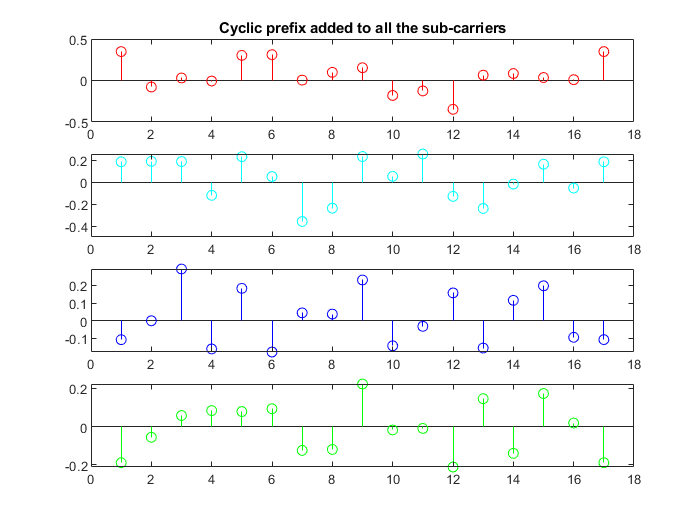

A1=Append_prefix(:,1);
A2=Append_prefix(:,2);
A3=Append_prefix(:,3);
A4=Append_prefix(:,4);
figure(5), subplot(4,1,1),stem(real(A1),'r'),title('Cyclic prefix added to all the sub-carriers')
subplot(4,1,2),stem(real(A2),'c')
subplot(4,1,3),stem(real(A3),'b')
subplot(4,1,4),stem(real(A4),'g')

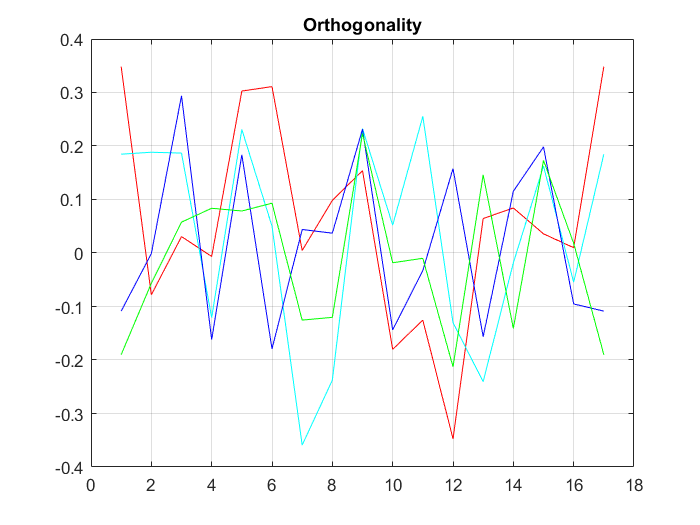


figure(11),plot((real(A1)),'r'),title('Orthogonality'),hold on ,plot((real(A2)),'c'),hold on ,
plot((real(A3)),'b'),hold on ,plot((real(A4)),'g'),hold on ,grid on

%Convert to serial stream for transmission
[rows_Append_prefix cols_Append_prefix]=size(Append_prefix)

rows_Append_prefix = 17

cols_Append_prefix = 4

len_ofdm_data = rows_Append_prefix*cols_Append_prefix

len_ofdm_data = 68

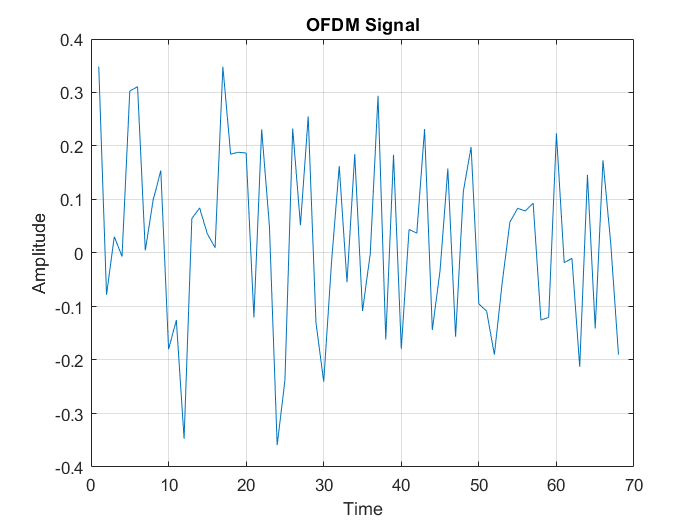

% OFDM signal to be transmitted
ofdm_signal = reshape(Append_prefix, 1, len_ofdm_data);
figure(6),plot(real(ofdm_signal)); xlabel('Time'); ylabel('Amplitude');
title('OFDM Signal');grid on;

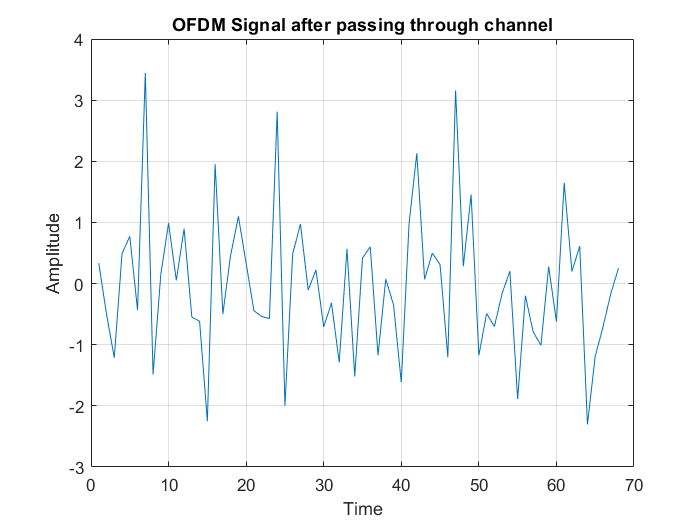

%...............................................................
%.............................................................
channel = randn(1,2) + sqrt(-1)*randn(1,2);
after_channel = filter(channel, 1, ofdm_signal);
awgn_noise = awgn(zeros(1,length(after_channel)),0);
recvd_signal = awgn_noise+after_channel; % With AWGN noise
figure(7),plot(real(recvd_signal)),xlabel('Time'); ylabel('Amplitude');
title('OFDM Signal after passing through channel');grid on;

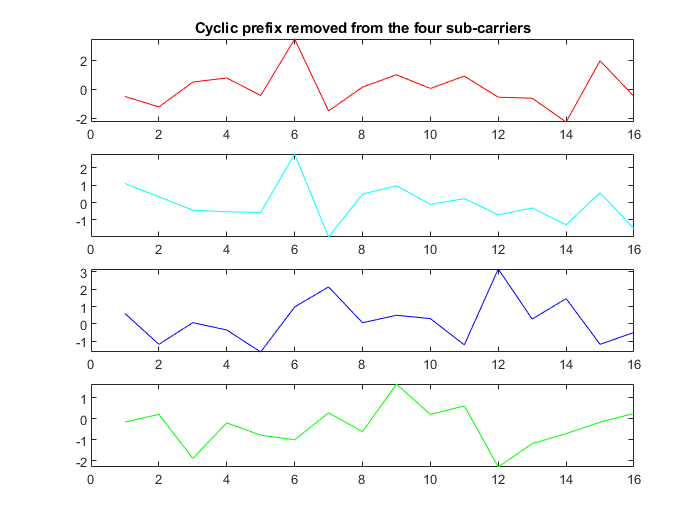

%...........................................................
%%..........................................................
recvd_signal_paralleled = reshape(recvd_signal,rows_Append_prefix, cols_Append_prefix);
%........................................................
%........................................................
% Remove cyclic Prefix
%.......................................................
%......................................................
recvd_signal_paralleled(1:cp_len,:)=[];
R1=recvd_signal_paralleled(:,1);
R2=recvd_signal_paralleled(:,2);
R3=recvd_signal_paralleled(:,3);
R4=recvd_signal_paralleled(:,4);
figure(8),plot((imag(R1)),'r'),subplot(4,1,1),plot(real(R1),'r'),
title('Cyclic prefix removed from the four sub-carriers')
subplot(4,1,2),plot(real(R2),'c')
subplot(4,1,3),plot(real(R3),'b')
subplot(4,1,4),plot(real(R4),'g')

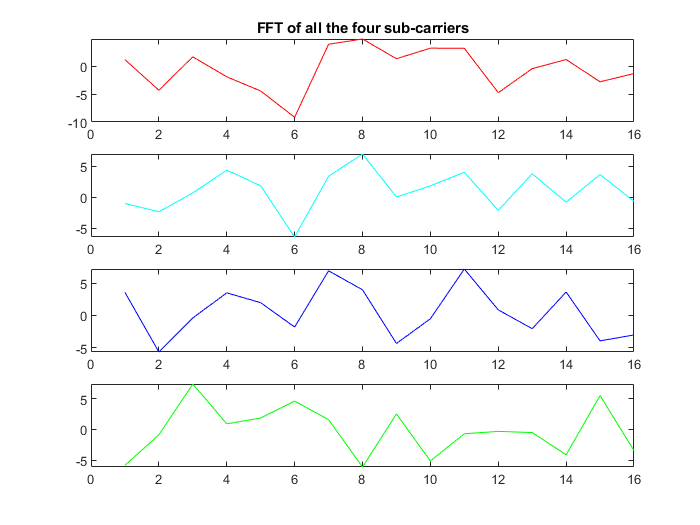

%...................................................
%...................................................
% FFT Of recievied signal
for i=1:number_of_subcarriers
% FFT
fft_data(:,i) = fft(recvd_signal_paralleled(:,i),16);
end
F1=fft_data(:,1);
F2=fft_data(:,2);
F3=fft_data(:,3);
F4=fft_data(:,4);
figure(9), subplot(4,1,1),plot(real(F1),'r'),title('FFT of all the four sub-carriers')
subplot(4,1,2),plot(real(F2),'c')
subplot(4,1,3),plot(real(F3),'b')
subplot(4,1,4),plot(real(F4),'g')

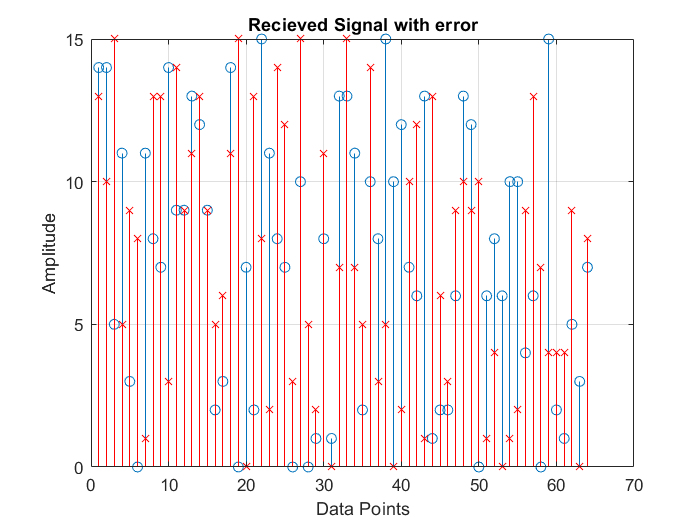

%................................
%..............................
% Signal Reconstructed
%..................................
%..................................
% Conversion to serial and demodulation
recvd_serial_data = reshape(fft_data, 1,(16*4));
qpsk_demodulated_data = pskdemod(recvd_serial_data,16);
figure(10)
stem(data)
hold on
stem(qpsk_demodulated_data,'rx');
grid on;xlabel('Data Points');ylabel('Amplitude');
title('Recieved Signal with error')

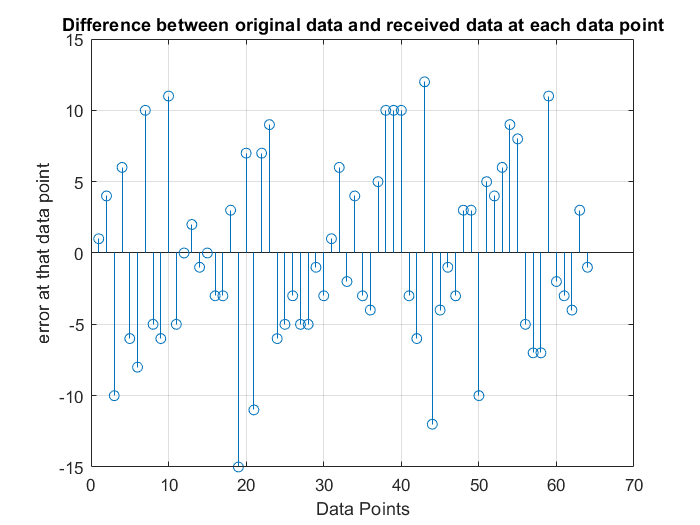

%..............................
%..............................
%Comparing the error 
%..............................
%..............................
er = zeros(no_of_data_bits, 1);
for i = 1:no_of_data_bits
    er(i)= data(i)- qpsk_demodulated_data(i); 
end
figure
stem(er);
title('Difference between original data and received data at each data point');
grid on;xlabel('Data Points');ylabel('error at that data point');